# Denoising Work Flow

## Add Files

addpath 'GT Folder'
addpath 'Real Noisy Images Folder'
addpath 'Common Functions'

## Load Image

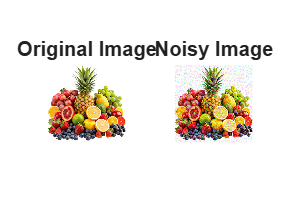

Image_name = 'fruits_imageGT.png';
%Image_name = 'balloons_noisy.png';

GT_substring = contains(Image_name, 'GT');
% Initialisation
d = 8; % depth of the n/w
imsize = -1;

if GT_substring
    % Get the ground truth image
    I = imread(fullfile('GT Folder', Image_name));
    img = imresize(I, [256 256]);
    %img = get_image(image, imsize);
    %img = crop_image(img, d);
    % Add noise to the image
    noisyImg = imnoise(img, 'gaussian', 0, 0.01); % Add Gaussian noise to the image
    % Display the original and noisy images for comparison
    figure;
    subplot(1, 2, 1), imshow(img), title('Original Image');
    subplot(1, 2, 2), imshow(noisyImg), title('Noisy Image');

elseif ~GT_substring
    % Load noisy image
    I = imread(fullfile('Real Noisy Images Folder', Image_name));
    noisyImg = imresize(I, [256 256]);
    %noisyImg = get_image(image, imsize);
    %noisyImg = crop_image(noisyImg, d);
    % Display the loaded noisy image
    figure;
    imshow(noisyImg), title('Loaded Noisy Image');
else
    assert(false, 'File Path or File name invalid')
end

## Define CNN and Noise Tensor

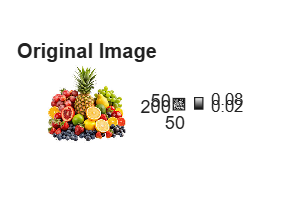

% --- Create Noise Tensor ---
input_depth = 3;
method = 'noise';
spatial_size = size(noisyImg, 1);
net_input = get_noise(input_depth, method, spatial_size);

%Visualize Noise
imagesc(net_input(:,:,2))
axis image
colormap gray
colorbar


% --- Create CNN ---
num_layers = d;
num_channels = 64;
num_classes = 3;
kernel_size = 3;
[a, b, ~] = size(noisyImg);
imgSize = [a, b, input_depth]; % Set the image size for the CNN

%net = buildCNN(num_layers, num_channels, kernel_size, imgSize, input_depth);
net = DipUnet3(imgSize, num_classes);
%net = InpaintUnet3(imgSize, num_classes);

% Compute number of parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    param = lrnables.Value{i};
    totalParams = totalParams + numel(extractdata(param));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 737035



% --- Define The Loss Function ---
%loss = mean((out - img_noisy).^2,'all');


function loss = computeLoss(out, img_noisy, lambda_tv) 
 
mse_loss = mean((out - img_noisy).^2, 'all'); 
%Total Variation: penalise spatial gradients in output 
dx = out(:, 2:end, :, :) - out(:,1:end-1, :, :); 
dy = out(2:end, :, :, :) - out(1:end-1, :, :, :); 
tv_loss = mean(abs(dx),'all') + mean(abs(dy), 'all'); 
loss = mse_loss + lambda_tv * tv_loss; 
end 
% Suggested: lambda_tv = 1e-4 to 1e-3 (tune for noise level)

## Optimization Step 1

function [loss, gradients, out, out_avg] = modelGradients(net, net_input_saved, img_noisy, out_avg, exp_weight, reg_noise_std)

    img_noisy = dlarray(img_noisy,'SSCB');

    if reg_noise_std > 0
        noise = randn(size(extractdata(net_input_saved)), 'single');
        noise = dlarray(noise, 'SSCB');
        net_input = net_input_saved + noise*reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass
    out = forward(net, net_input);

    % Loss (MSE)
    loss = mean((out - img_noisy).^2,'all');
    %loss = computeLoss(out, img_noisy, 1e-32);

    % Output smoothing (detach)
    out_detached = dlarray(extractdata(out),'SSCB');

    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg*exp_weight + out_detached*(1-exp_weight);
    end

    % Gradients
    gradients = dlgradient(loss, net.Learnables);

end

## Optimization Step 2

trailingAvg   = [];
trailingAvgSq = [];
reg_noise_std = 1/30;

if GT_substring
    img_gt = img;
    img_gt = im2double(img_gt);
end

PLOT = 1; % 1 for plotting and 0 otherwise
LR = 1e-4;
show_every = 10;
exp_weight = 0.99;
num_iter = 10000;
out_avg = [];
last_net = [];
last_learnables = [];
psrn_noisy_last = 0;
psnr_noisy_last = -inf;


noisyImg_nom = im2double(noisyImg);

% Convert net_input to dlarray format
%net_input = dlarray(net_input, 'SSCB');
%net_input_saved = dlarray(net_input, 'SSCB');
net_input_saved = dlarray(single(net_input), 'SSCB');

% --- Training Loop ---
for iter = 1:num_iter
    % Call function for forward pass
    [loss, gradients, out, out_avg] = dlfeval(@modelGradients, net, net_input_saved, noisyImg_nom, out_avg, exp_weight, reg_noise_std);
    
    
    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients,trailingAvg, trailingAvgSq, iter, LR);
    

    % --- Convert dlarray to numeric ---
    out_num = double(gather(extractdata(out)));
    out_num = out_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);

    noisyImg_num = im2double(noisyImg);

    %--- Compute PSNR ---
    psnr_noisy = psnr(out_num, noisyImg_num);
    if GT_substring
        img_numGT = im2double(img_gt);
        psnr_gt = psnr(out_num, img_numGT);
        psnr_gt_sm = psnr(out_avg_num, img_numGT);
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f PSNR_gt: %.4f PSNR_gt_sm: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy, psnr_gt, psnr_gt_sm);
    else
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy);
    end
    
    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        % Clip to [0, 1]
        out_plt = min(max(out_num, 0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);
        % Plot side by side
        fig = figure(1); clf
        set(fig, 'Visible', 'on');
        subplot(1,2,1);
        imagesc(out_plt); colormap gray; axis image off;
        if GT_substring
            title(sprintf('Output (Iter %d; PSNR GT %d)', iter,psnr_gt));
        else
            title(sprintf('Output (Iter %d; PSNR Noisy %d)', iter,psnr_noisy));
        end

        subplot(1,2,2);
        imagesc(out_avg_plt); colormap gray; axis image off;
        title('Smoothed output')
        drawnow 
    end

    % --- Back Tracking Logic ---
    if  mod(iter, show_every) ~= 0
        if psnr_noisy - psnr_noisy_last < -5
            fprintf('\n Falling back to previous checkpoint.\n');
            % Restore weights
            net.Learnables.Value = last_learnables;
            break; % stop training
        else
            % Save current weights
            last_learnables = net.Learnables.Value;
            psnr_noisy_last = psnr_noisy;
        end
    end

end

Iteration 00001 Loss 0.175570 PSNR_noisy: 7.5555 PSNR_gt: 7.2664 PSNR_gt_sm: 7.2664
Iteration 00002 Loss 0.187607 PSNR_noisy: 7.2675 PSNR_gt: 6.9810 PSNR_gt_sm: 7.2728
Iteration 00003 Loss 0.159279 PSNR_noisy: 7.9784 PSNR_gt: 7.6857 PSNR_gt_sm: 7.2847
Iteration 00004 Loss 0.166211 PSNR_noisy: 7.7934 PSNR_gt: 7.5009 PSNR_gt_sm: 7.2960
Iteration 00005 Loss 0.168644 PSNR_noisy: 7.7303 PSNR_gt: 7.4382 PSNR_gt_sm: 7.3077
Iteration 00006 Loss 0.166652 PSNR_noisy: 7.7819 PSNR_gt: 7.4889 PSNR_gt_sm: 7.3183
Iteration 00007 Loss 0.164906 PSNR_noisy: 7.8276 PSNR_gt: 7.5400 PSNR_gt_sm: 7.3291
Iteration 00008 Loss 0.153412 PSNR_noisy: 8.1414 PSNR_gt: 7.8446 PSNR_gt_sm: 7.3430
Iteration 00009 Loss 0.154644 PSNR_noisy: 8.1067 PSNR_gt: 7.8098 PSNR_gt_sm: 7.3569
Iteration 00010 Loss 0.156765 PSNR_noisy: 8.0475 PSNR_gt: 7.7554 PSNR_gt_sm: 7.3705
Iteration 00011 Loss 0.144369 PSNR_noisy: 8.4053 PSNR_gt: 8.1089 PSNR_gt_sm: 7.3859
Iteration 00012 Loss 0.155936 PSNR_noisy: 8.0705 PSNR_gt: 7.7784 PSNR_gt_sm:

10.5909
Iteration 00382 Loss 0.078457 PSNR_noisy: 11.0537 PSNR_gt: 10.8310 PSNR_gt_sm: 10.5948
Iteration 00383 Loss 0.077173 PSNR_noisy: 11.1254 PSNR_gt: 10.9089 PSNR_gt_sm: 10.5992
Iteration 00384 Loss 0.076534 PSNR_noisy: 11.1614 PSNR_gt: 10.9422 PSNR_gt_sm: 10.6041
Iteration 00385 Loss 0.076338 PSNR_noisy: 11.1726 PSNR_gt: 10.9557 PSNR_gt_sm: 10.6089
Iteration 00386 Loss 0.076260 PSNR_noisy: 11.1770 PSNR_gt: 10.9581 PSNR_gt_sm: 10.6137
Iteration 00387 Loss 0.077633 PSNR_noisy: 11.0995 PSNR_gt: 10.8859 PSNR_gt_sm: 10.6177
Iteration 00388 Loss 0.076197 PSNR_noisy: 11.1806 PSNR_gt: 10.9688 PSNR_gt_sm: 10.6227
Iteration 00389 Loss 0.076182 PSNR_noisy: 11.1815 PSNR_gt: 10.9682 PSNR_gt_sm: 10.6276
Iteration 00390 Loss 0.076650 PSNR_noisy: 11.1549 PSNR_gt: 10.9394 PSNR_gt_sm: 10.6320
Iteration 00391 Loss 0.074617 PSNR_noisy: 11.2716 PSNR_gt: 11.0556 PSNR_gt_sm: 10.6374
Iteration 00392 Loss 0.075781 PSNR_noisy: 11.2044 PSNR_gt: 10.9943 PSNR_gt_sm: 10.6428
Iteration 00393 Loss 0.075852 PSNR_

10.7271
Iteration 00412 Loss 0.073822 PSNR_noisy: 11.3181 PSNR_gt: 11.1070 PSNR_gt_sm: 10.7321
Iteration 00413 Loss 0.074129 PSNR_noisy: 11.3001 PSNR_gt: 11.0913 PSNR_gt_sm: 10.7367
Iteration 00414 Loss 0.073990 PSNR_noisy: 11.3083 PSNR_gt: 11.0958 PSNR_gt_sm: 10.7414
Iteration 00415 Loss 0.075151 PSNR_noisy: 11.2406 PSNR_gt: 11.0296 PSNR_gt_sm: 10.7457
Iteration 00416 Loss 0.074739 PSNR_noisy: 11.2645 PSNR_gt: 11.0537 PSNR_gt_sm: 10.7501
Iteration 00417 Loss 0.074011 PSNR_noisy: 11.3071 PSNR_gt: 11.0931 PSNR_gt_sm: 10.7548
Iteration 00418 Loss 0.075938 PSNR_noisy: 11.1954 PSNR_gt: 10.9804 PSNR_gt_sm: 10.7587
Iteration 00419 Loss 0.074909 PSNR_noisy: 11.2547 PSNR_gt: 11.0427 PSNR_gt_sm: 10.7629
Iteration 00420 Loss 0.073763 PSNR_noisy: 11.3216 PSNR_gt: 11.1129 PSNR_gt_sm: 10.7677
Iteration 00421 Loss 0.074059 PSNR_noisy: 11.3042 PSNR_gt: 11.0963 PSNR_gt_sm: 10.7723
Iteration 00422 Loss 0.073765 PSNR_noisy: 11.3215 PSNR_gt: 11.1126 PSNR_gt_sm: 10.7768
Iteration 00423 Loss 0.073362 PSNR_

## See